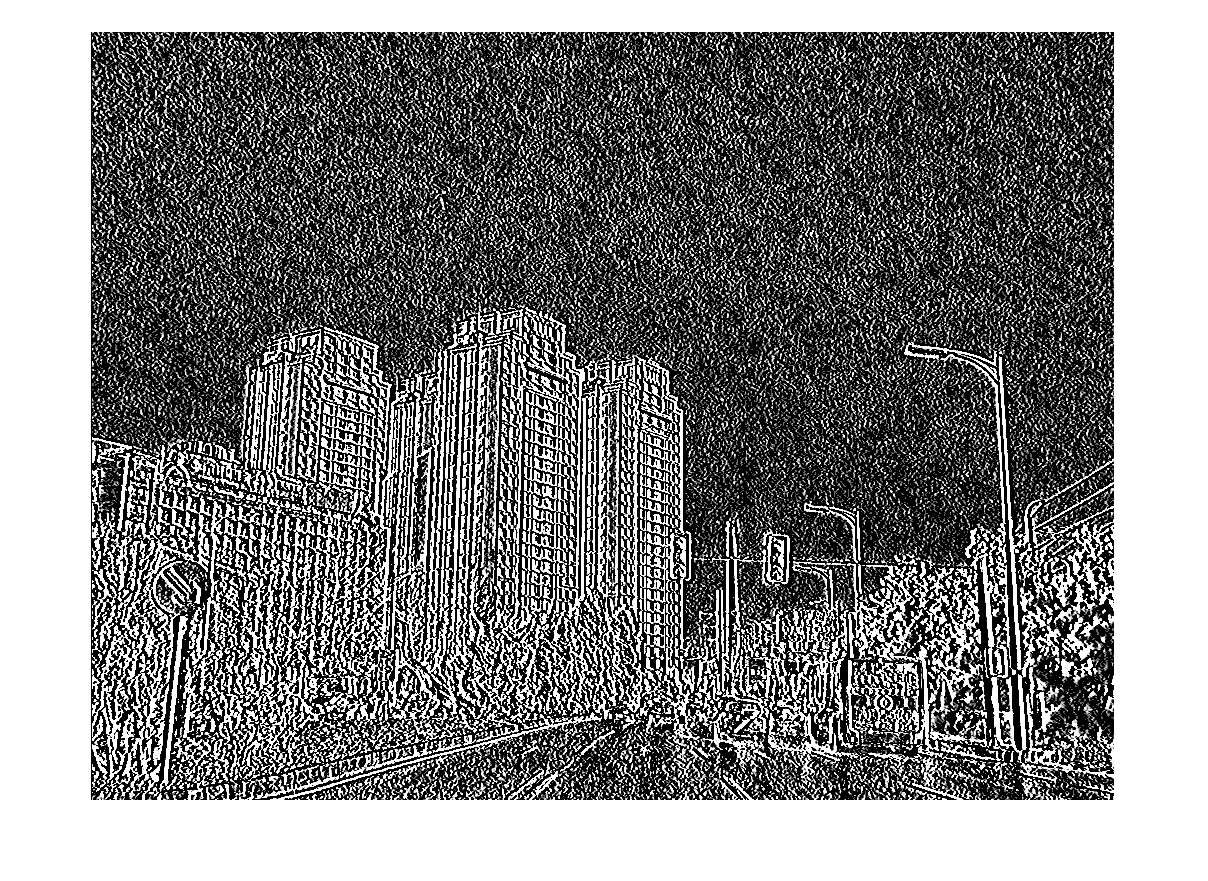

%Test original MIND
clear all, close all;
folder = {'descriptor','external_code','ssim'};
for it=1:length(folder)
    p = genpath(folder{it});
    addpath(p);
end
folderTh = 'M3FD2/Ir/';
folderVis = 'M3FD2/Vis/';
imagesRgb = dir(folderVis);
imagesLwir = dir(folderTh);

k = 2200;
ws = 35;
idexes = uint8.empty(200,0);

nameRgb = imagesRgb(k).name;
nameLwir = imagesLwir(k).name;
im_rgb = im2gray(imread(strcat(folderVis,nameRgb)));
im_lwirori = im2gray(imread(strcat(folderTh,nameLwir)));
% [ x, y, scores, Ix, Iy, Ixy, H ] = extractFeatures( im_rgb );
% [ x2, y2, scores2, Ix2, Iy2, Ixy2, H2 ] = extractFeatures( im_lwirori );
% imshow(rescale(Ix))
% imshow(rescale(Iy))
% imshow(rescale(Ixy))
% min(H),max(H)
% imshow((rescale(H)))
% imshow(rescale(Ix2))
% imshow(2.72.^(-rescale(Iy2)))
% imshow(Ixy2)
% imshow(exp(-rescale(H2)))
[Ix, Iy, Ixy, Iyx, C] = imcurl(im_rgb);
[Ix2, Iy2,Ixy2, Iyx2, C2] = imcurl(im_lwirori);
figure, imshow(Ix);

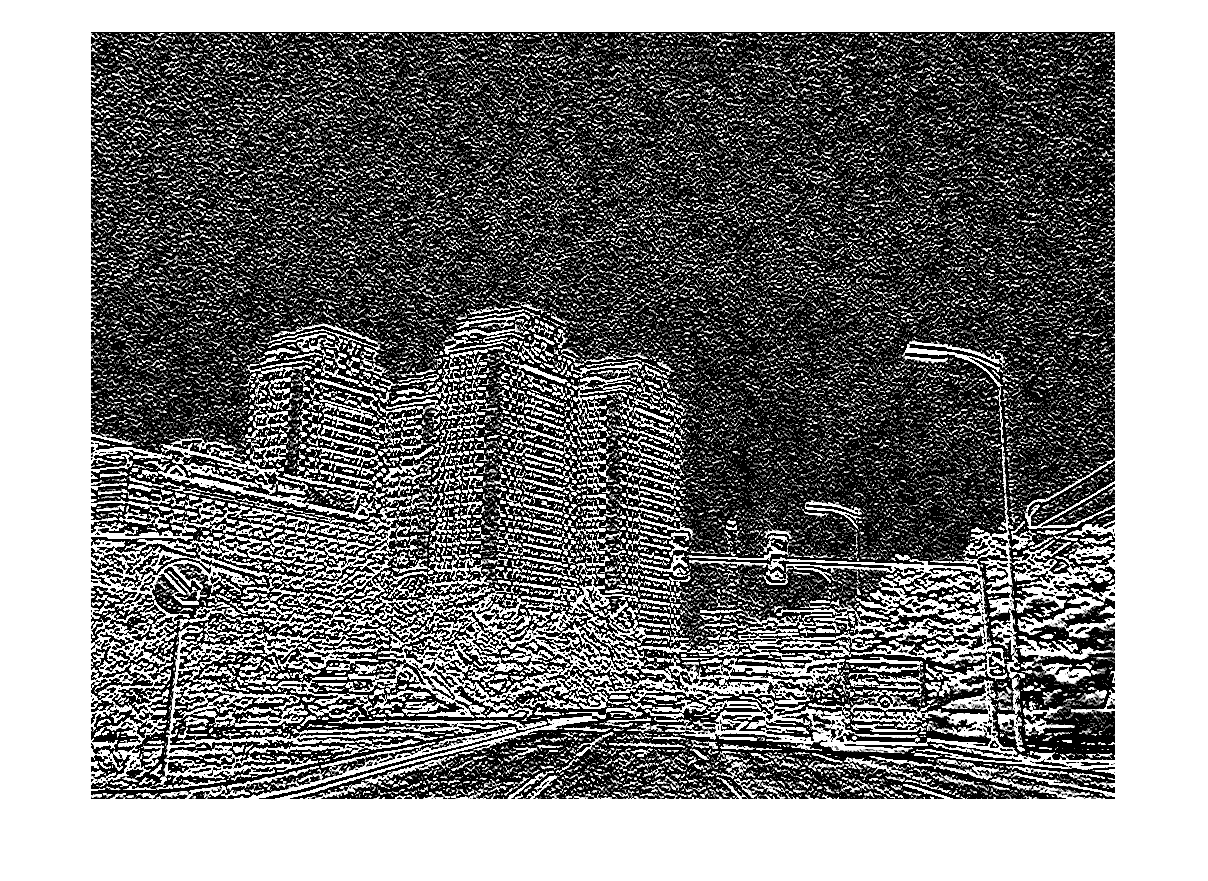

figure, imshow(Iy);

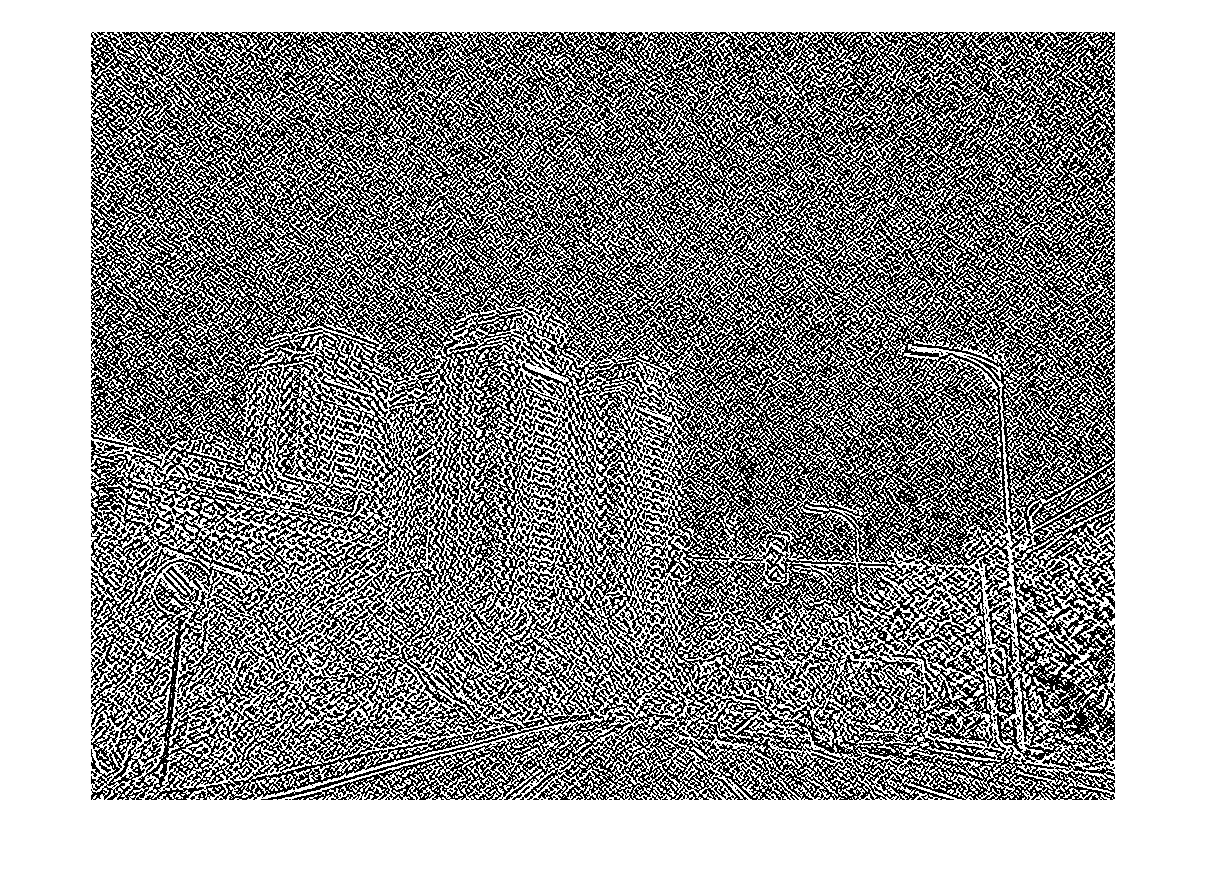

figure, imshow(Ixy);

figure, imshow(Iyx);

%figure, imshow(exp(-rescale(Ixy+Iyx)));
min(C,[],'all'),max(C,[],'all')

ans = 0

ans = 1.9327e-12

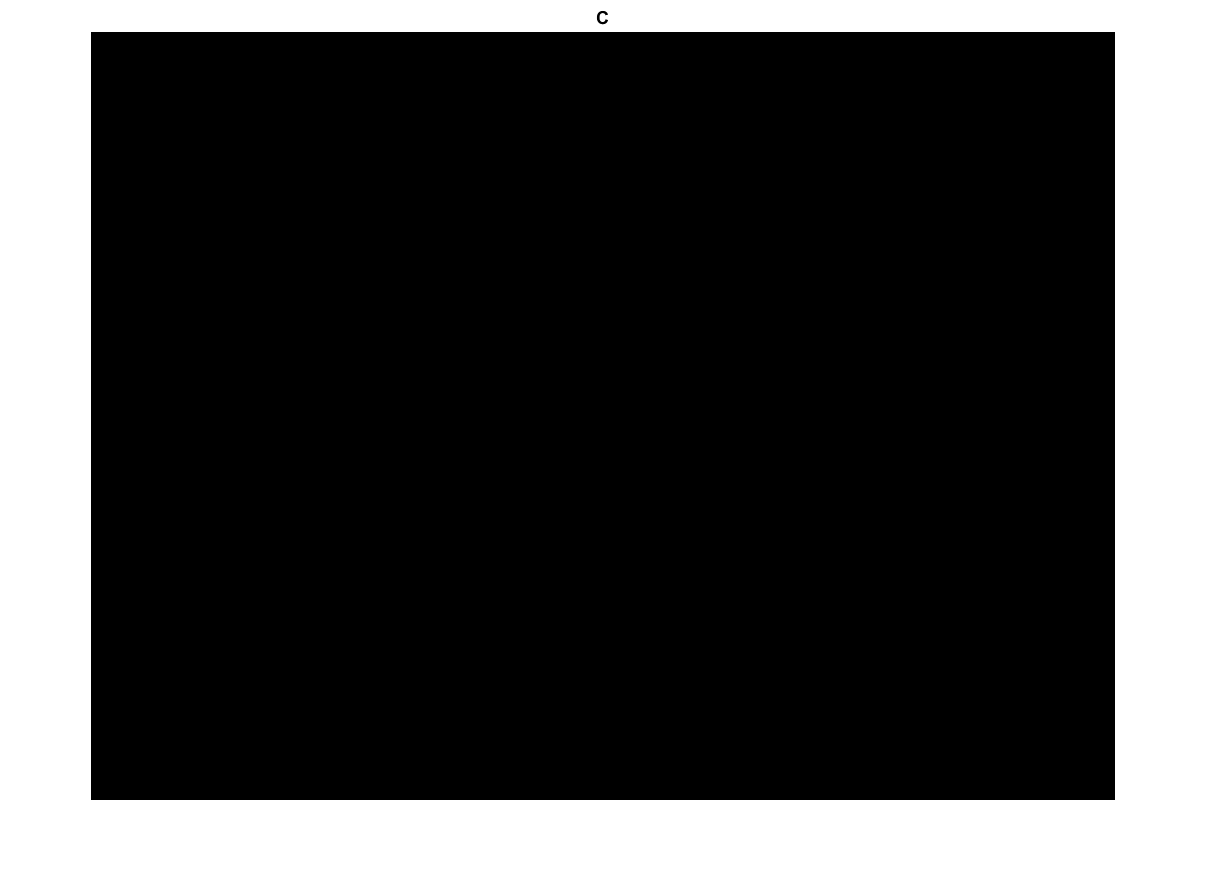

figure, imshow(C), title('C');

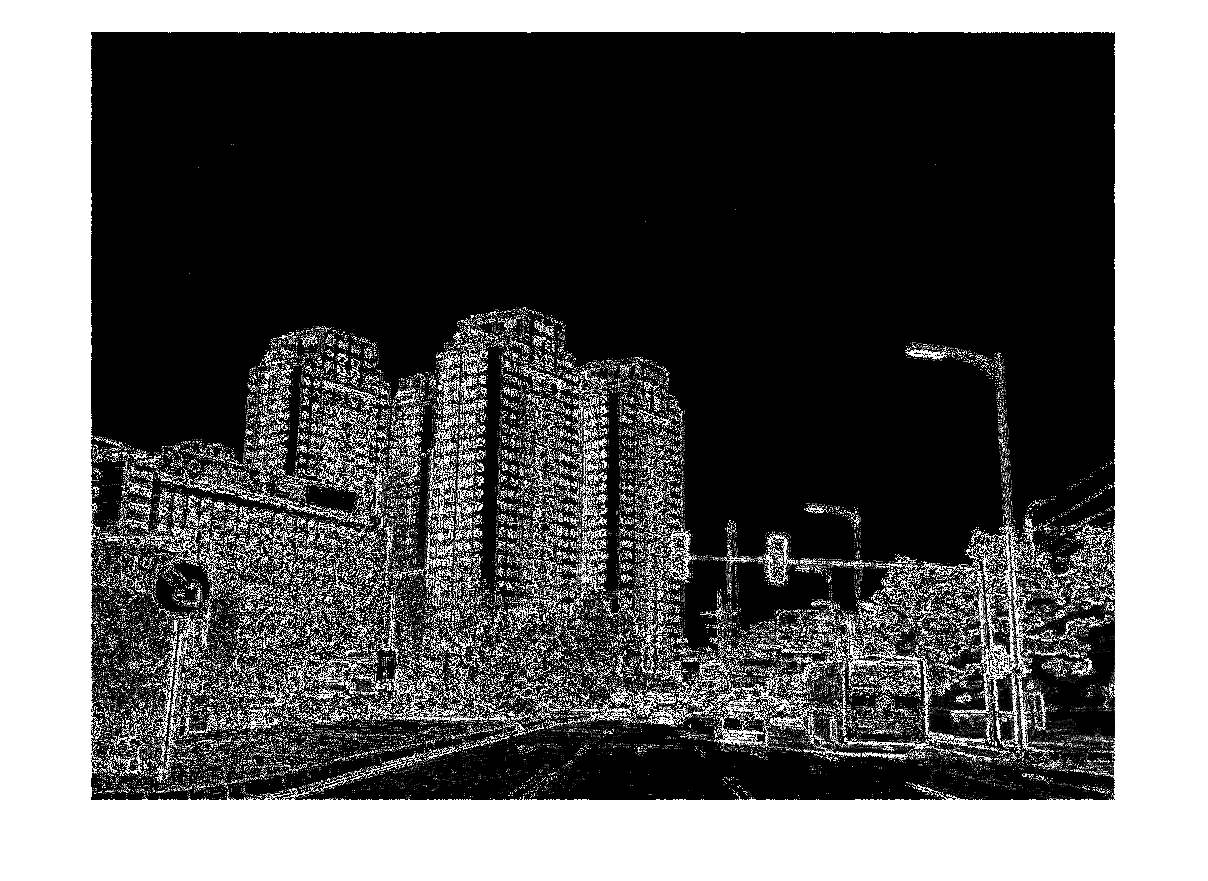

figure, imshow((10^13)*C);

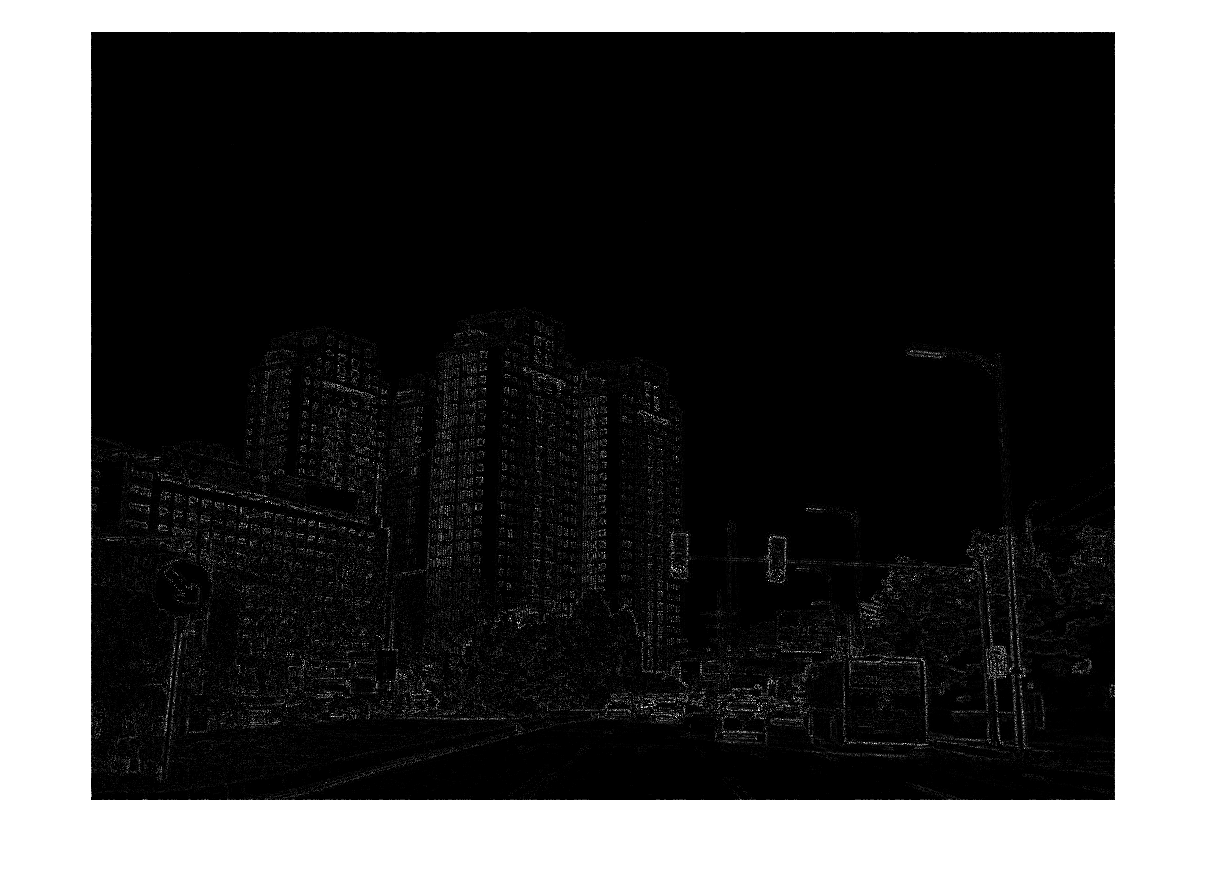

figure, imshow(rescale(abs(C)));

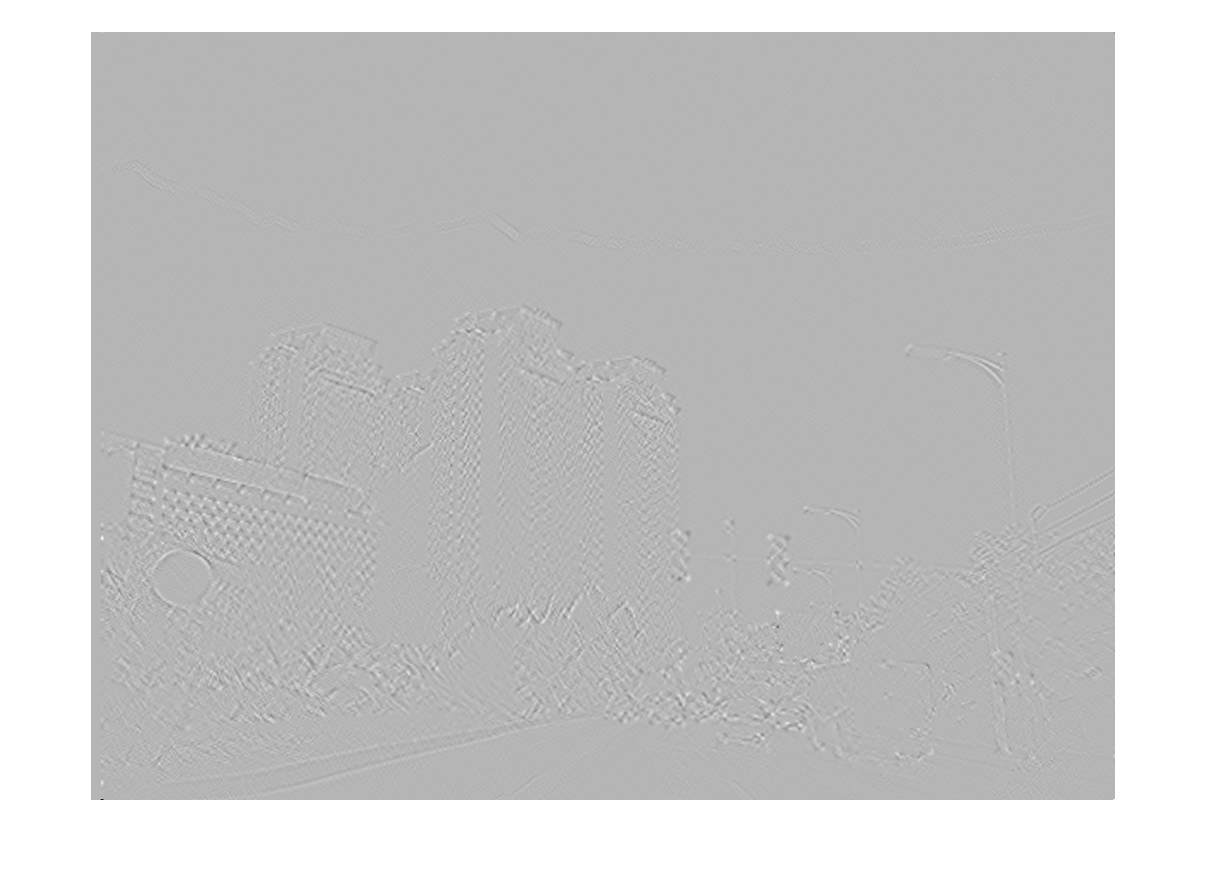

figure, imshow(rescale(Ixy2+Iyx2));

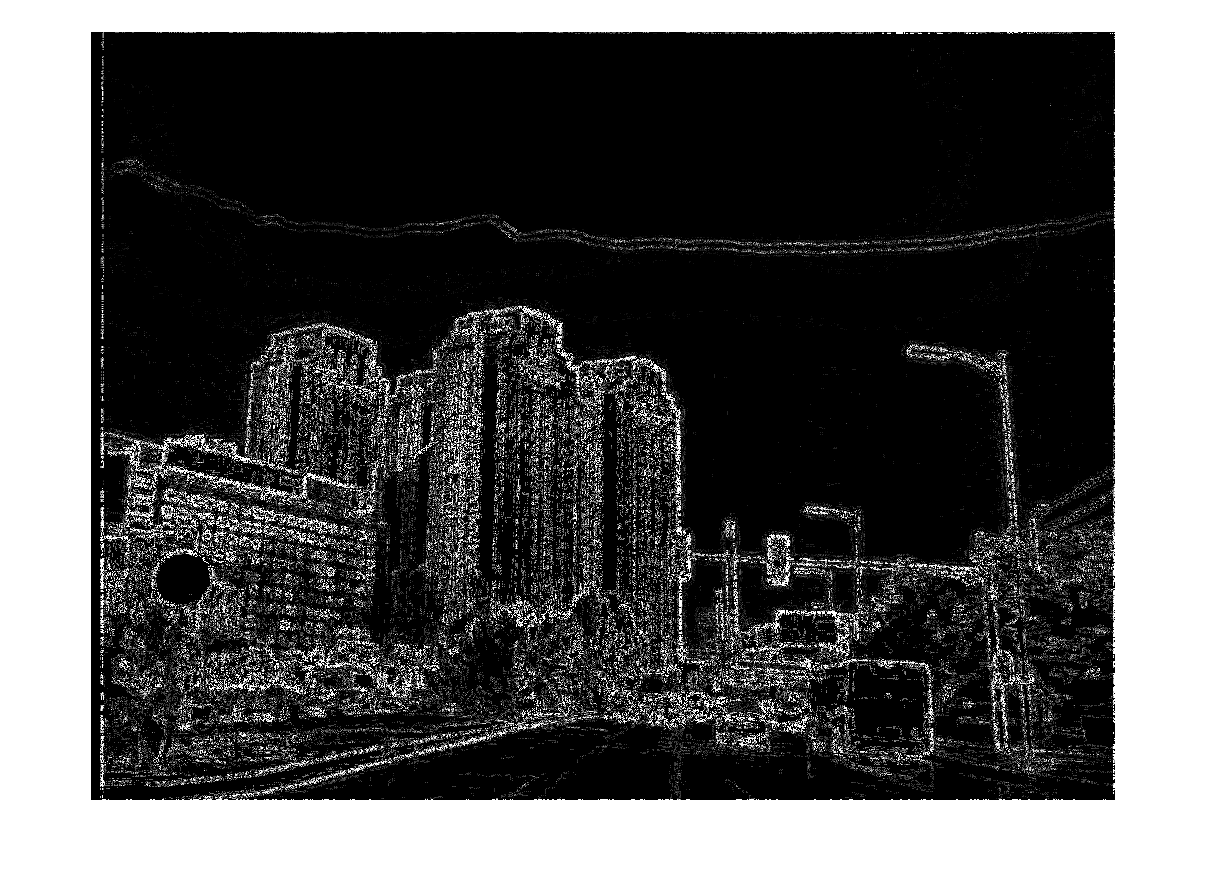

figure, imshow((10^13)*C2);

% mid1 = MIND_descriptor2D(im_rgb);
% mid11 = MINDescriptor2DMod(im_rgb,0,0.5,2.72);
% mid2 = MIND_descriptor2D(im_lwirori);
% mid3 = MINDescriptor2DMod(im_lwirori,0,0.5,2.72);
% figure, imshow(im_rgb);
% figure, imshow(im_lwirori);
% figure, imshow(mid1(:,:,1:3));
% figure, imshow(mid11(:,:,1:3));
% figure, imshow(mid2(:,:,1:3));
% figure, imshow(mid3(:,:,1:3));